# MAE 204 HW6

## Part 1

### Exercise 5.26

clear all; close all;
clc;

thetalist = [pi()/2;pi()/2;pi()/2;pi()/2;pi()/2;pi()/2;pi()/2]

thetalist =     1.5708
    1.5708
    1.5708
    1.5708
    1.5708
    1.5708
    1.5708


w1 = [0;0;1];
w2 = [0;1;0];
w3 = w1;
w4 = w2;
w5 = w1;
w6 = w2;
w7 = w1;

q1 = [0;0;0];
q2 = q1;
q3 = q1;
q4 = [45; 0; 550];
q5 = [0;0; 850];
q6 = q5;
q7 = q5;

S1 = S_from_wq(w1,q1);
S2 = S_from_wq(w2,q2);
S3 = S_from_wq(w3,q3);
S4 = S_from_wq(w4,q4);
S5 = S_from_wq(w5,q5);
S6 = S_from_wq(w6,q6);
S7 = S_from_wq(w7,q7);

% M Matrix
M = [1 0 0 0;0 1 0 45;0 0 1 910;0 0 0 1];

% Calculating BList
B1 = StoB(S1,M);
B2 = StoB(S2,M);
B3 = StoB(S3,M);
B4 = StoB(S4,M);
B5 = StoB(S5,M);
B6 = StoB(S6,M);
B7 = StoB(S7,M);

% Calculating Body Jacobian
BodyJ = JacobianBody([B1 B2 B3 B4 B5 B6 B7],thetalist)

BodyJ =     0.0000   -0.0000    1.0000    0.0000   -0.0000    1.0000         0
   -0.0000    1.0000    0.0000   -0.0000    1.0000    0.0000         0
    1.0000    0.0000   -0.0000    1.0000    0.0000         0    1.0000
 -390.0000   60.0000    0.0000 -345.0000   60.0000    0.0000  -45.0000
  595.0000    0.0000  -60.0000   45.0000    0.0000  -60.0000         0
    0.0000 -595.0000  390.0000    0.0000   -0.0000   45.0000         0



% Angular and Linear Jacobian
J_w = BodyJ(1:3,:)

J_w =     0.0000   -0.0000    1.0000    0.0000   -0.0000    1.0000         0
   -0.0000    1.0000    0.0000   -0.0000    1.0000    0.0000         0
    1.0000    0.0000   -0.0000    1.0000    0.0000         0    1.0000


J_v = BodyJ(4:6,:)

J_v =  -390.0000   60.0000    0.0000 -345.0000   60.0000    0.0000  -45.0000
  595.0000    0.0000  -60.0000   45.0000    0.0000  -60.0000         0
    0.0000 -595.0000  390.0000    0.0000   -0.0000   45.0000         0



% Calculating Eigenvalues
A_w = J_w*J_w'

A_w =     2.0000   -0.0000    0.0000
   -0.0000    2.0000    0.0000
    0.0000    0.0000    3.0000


[V1,D1] = eig(round(A_w,4))

V1 =      1     0     0
     0     1     0
     0     0     1


D1 =      2     0     0
     0     2     0
     0     0     3


sq_D1 = sqrt(D1)

sq_D1 =     1.4142         0         0
         0    1.4142         0
         0         0    1.7321


A_v = J_v*J_v'

A_v = 	1.0e+05 *

    2.8035   -2.4758   -0.3570
   -2.4758    3.6325   -0.2610
   -0.3570   -0.2610    5.0815


[V2,D2] = eig(round(A_v,4))

V2 =     0.7599   -0.0424   -0.6487
    0.6424   -0.1036    0.7593
    0.0994    0.9937    0.0515


D2 = 	1.0e+05 *

    0.6637         0         0
         0    5.1239         0
         0         0    5.7298


sq_D2 = sqrt(D2)

sq_D2 =   257.6323         0         0
         0  715.8160         0
         0         0  756.9565


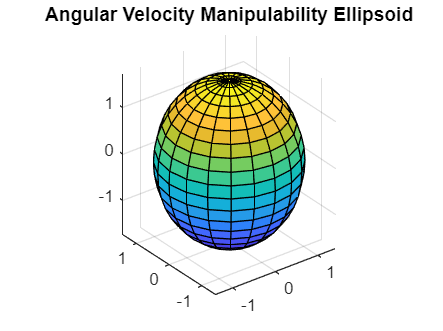


% Plotting
figure(1)
ellipsoid(0,0,0,sq_D1(1,1),sq_D1(2,2),sq_D1(3,3))
axis equal
title('Angular Velocity Manipulability Ellipsoid')

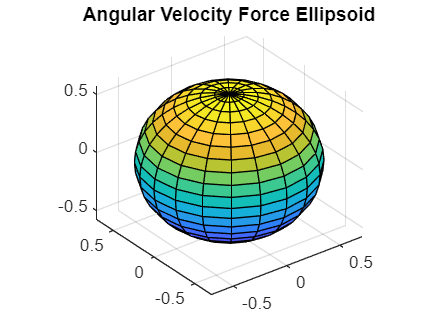


figure(2)
ellipsoid(0,0,0,1/sq_D1(1,1),1/sq_D1(2,2),1/sq_D1(3,3))
axis equal
title('Angular Velocity Force Ellipsoid')

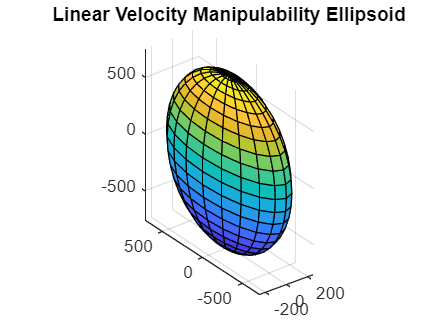


figure(3)
ellipsoid(0,0,0,sq_D2(1,1),sq_D2(2,2),sq_D2(3,3))
axis equal
title('Linear Velocity Manipulability Ellipsoid')

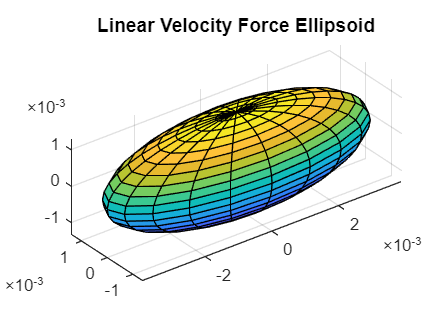


figure(4)
ellipsoid(0,0,0,1/sq_D2(1,1),1/sq_D2(2,2),1/sq_D2(3,3))
axis equal
title('Linear Velocity Force Ellipsoid')

### Exercise 6.8

syms x y
g = [x^2 - 4; y^2-9]

$$g = \left(\begin{array}{c} x^{2}-4\\ y^{2}-9 \end{array}\right)$$

diff_g = [2*x 0; 0 2*y]

$$diff\_g = \left(\begin{array}{cc} 2\,x & 0\\ 0 & 2\,y \end{array}\right)$$

det_diff_g = det(diff_g);

xi = [x;y]-diff_g\g;

x1_sub = subs(xi,x,1);
y1_sub = subs(x1_sub,y,1);
first_iteration = vpa(y1_sub)

$$first\_iteration = \left(\begin{array}{c} 2.5\\ 5.0 \end{array}\right)$$


x2_sub = subs(xi,x,y1_sub(1));
y2_sub = subs(x2_sub,y,y1_sub(2));
second_iteration = vpa(y2_sub)

$$second\_iteration = \left(\begin{array}{c} 2.05\\ 3.4 \end{array}\right)$$

## Part 2

clear all; close all;
clc;

w1 = [0;0;1];
w2 = [0;1;0];
w3 = w2;
w4 = w2;
w5 = -w1;
w6 = w2;

q1 = [0;-300;88];
q2 = q1+[0;0;152];
q3 = q2+[244;120;0];
q4 = q3+[213;-93;0];
q5 = q4+[0;104; 0];
q6 = q5+[0;0;-85];

S1 = S_from_wq(w1,q1);
S2 = S_from_wq(w2,q2);
S3 = S_from_wq(w3,q3);
S4 = S_from_wq(w4,q4);
S5 = S_from_wq(w5,q5);
S6 = S_from_wq(w6,q6);
Slist = [S1 S2 S3 S4 S5 S6]

Slist =      0     0     0     0     0     0
     0     1     1     1     0     1
     1     0     0     0    -1     0
  -300  -240  -240  -240   169  -155
     0     0     0     0   457     0
     0     0   244   457     0   457


d = 155;
M = [1 0 0 457;0 1 0 -77+d;0 0 1 155;0 0 0 1]

M =      1     0     0   457
     0     1     0    78
     0     0     1   155
     0     0     0     1



B1 = StoB(S1,M);
B2 = StoB(S2,M);
B3 = StoB(S3,M);
B4 = StoB(S4,M);
B5 = StoB(S5,M);
B6 = StoB(S6,M);
Blist = [B1 B2 B3 B4 B5 B6]

Blist =      0     0     0     0     0     0
     0     1     1     1     0     1
     1     0     0     0    -1     0
  -378   -85   -85   -85   247     0
   457     0     0     0     0     0
     0  -457  -213     0     0     0



thetalist = [-30;-90;90;-90;-90;150];
thetalist=thetalist*pi/180

thetalist =    -0.5236
   -1.5708
    1.5708
   -1.5708
   -1.5708
    2.6180


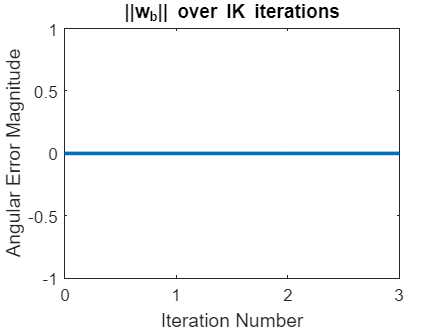

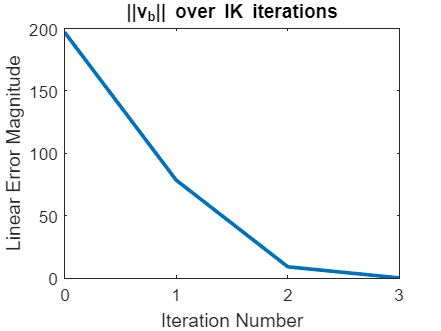

newthetalistCustom =    -0.2954
   -0.8896
    1.3390
   -2.0202
   -1.5708
    2.8462


T = [0 0 1 450; -1 0 0 -300; 0 -1 0 90; 0 0 0 1];
eomg = 0.001;
ev = 0.1;

newthetalistCustom = IKinBodyIterations([B1 B2 B3 B4 B5 B6],M,T, thetalist, eomg, ev)

round(newthetalistCustom*180/pi(),2)

ans =   -16.9200
  -50.9700
   76.7200
 -115.7500
  -90.0000
  163.0800


%newthetalistB = IKinBody(Blist,M,T, thetalist, eomg, ev)

%newthetalistS = IKinSpace(Slist,M,T, thetalist, eomg, ev)
